Load a map

cd('/Users/cudmore/Dropbox/matlab');
mapPath = '/Users/cudmore/Dropbox/MapManagerData/richard/rr30a';
obj = mmMap(mapPath);

Pull a stat

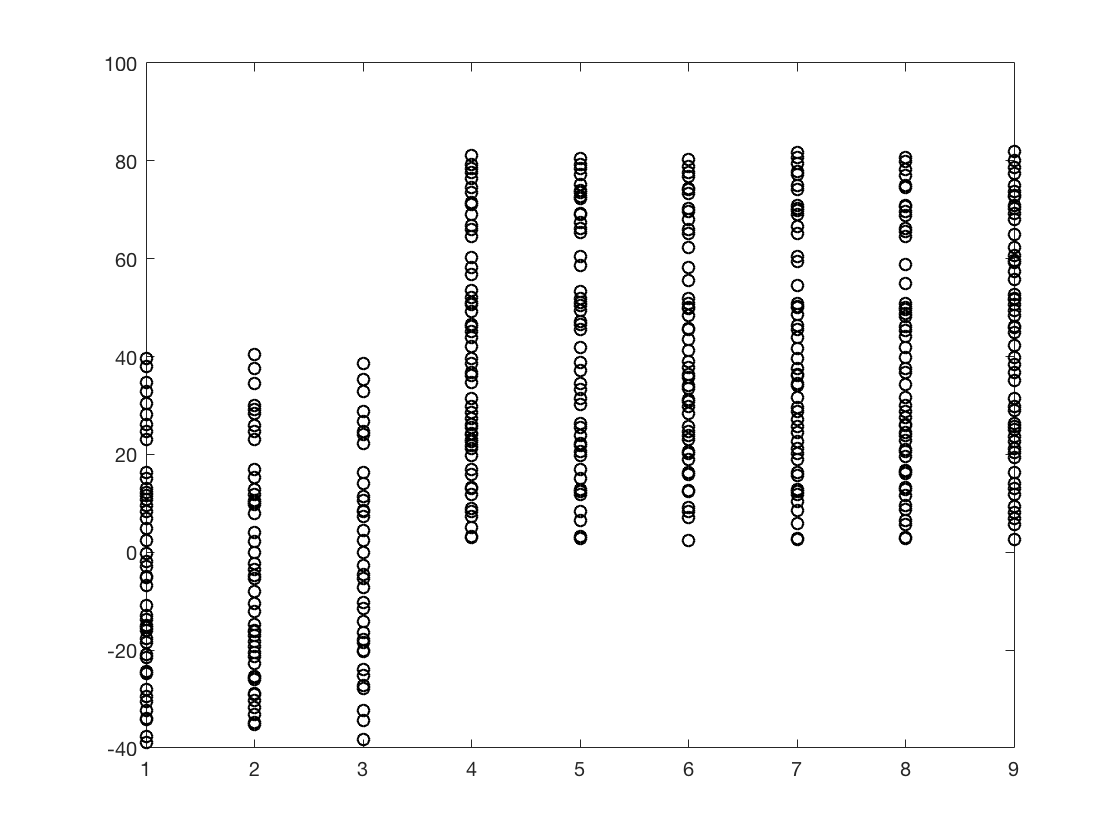

ps = mmMap.defaultPlotStruct();
ps.stat = 'pDist'; %'ubssSum';
ps.mapsegment = 0; % set to NaN for all
ps = obj.GetMapValues(ps);
plot(ps.x, ps.y,'ok');

Pull and plot two stats

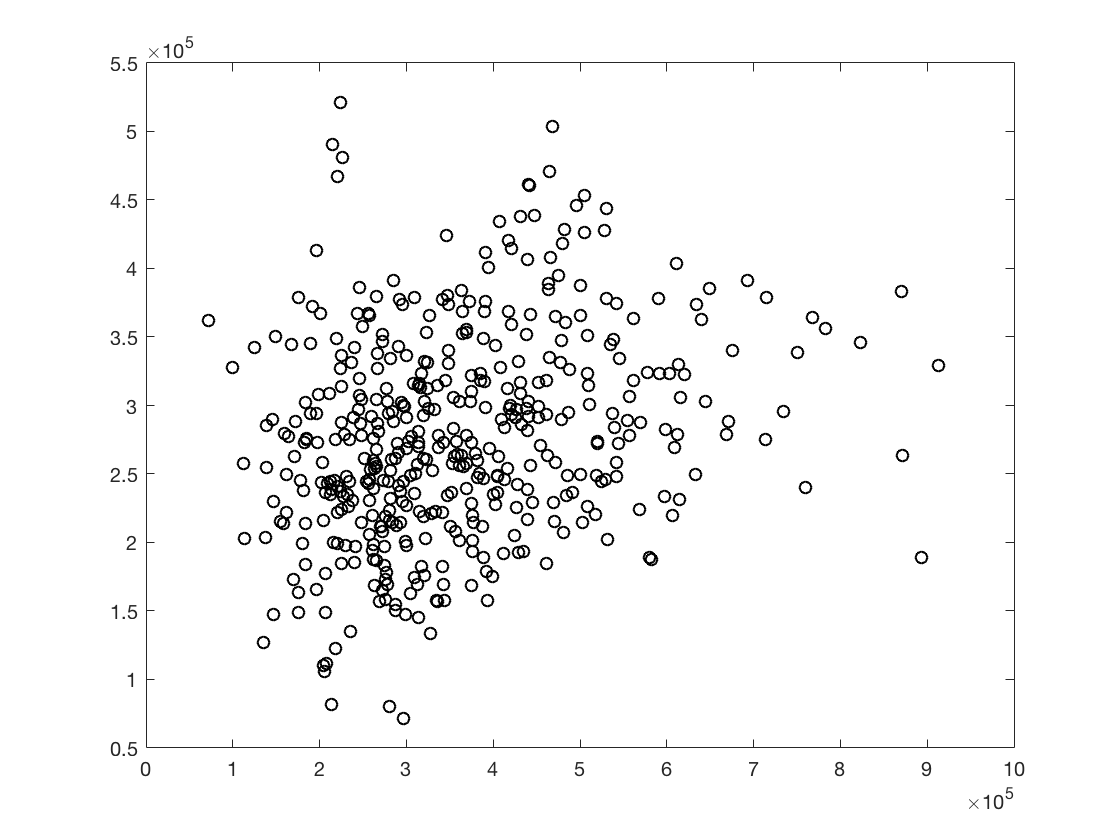

ps1 = mmMap.defaultPlotStruct();
ps1.stat = 'ubssSum'; % background subtracted spine sum
ps1.channel = 2;
ps1.mapsegmentid = NaN; % set to NaN for all
ps1 = obj.GetMapValues(ps1);

ps2 = ps1; % make sure they match (e.g. mapsegmentid)
ps2.stat = 'ubsdSum'; %'ubssSum';
ps2.channel = 1;
ps2 = obj.GetMapValues(ps2);

plot(ps1.y, ps2.y,'ok');